videoname = 'Lov-2017-11-06T18_22_43_compressed.avi';
video = read(VideoReader(videoname));
background = imread('background2017-11-06T18_32_18.bmp');
video = (background - video);
% video = imcomplement(video);
try
    d = gpuDevice;
    gpuAvailable = d.SupportsDouble;
catch
    gpuAvailable = false;
end


## Clip it

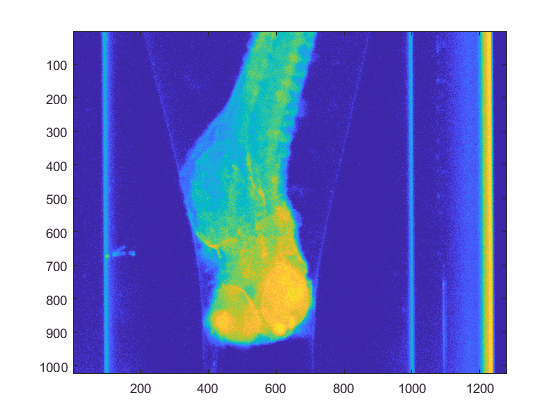

best_startframe = 10;
best_endframe = 379;
colorchannel = 3;
vid_data = squeeze(video(:,:,colorchannel,best_startframe:best_endframe));
angles = linspace(0,2*pi, best_endframe-best_startframe+1);
% clear video
numslices = size(vid_data,1);
image_width = size(vid_data,2);
numframes = size(vid_data,3);
imagesc(vid_data(:,:,1));

## Find Hough points at the top and bottom of every frame

capillary_endpoints = find_hough_points(vid_data);



## Take sinograms of the top and bottom

% 
% topsino = double(squeeze(vid_data(1,:,:)) -0);
% imagesc(topsino);
% title('Top sinogram');
% [top_offset, top_midpoints, top_fitted] = get_sin_offset(topsino);
% hold on
% plot(top_midpoints, '--', 'LineWidth',2,'Color','red');
% plot(top_fitted, '-', 'LineWidth',3,'Color','green');
% hold off
% 
% bottomsino = double(squeeze(vid_data(numslices,:,:)) -0);
% imagesc(bottomsino);
% title('Bottom sinogram');
% % bottom_midpoints = get_capillary_midpoint(bottomsino);
% [bottom_offset, bottom_midpoints, bottom_fitted] = get_sin_offset(bottomsino);
% hold on
% plot(bottom_midpoints, '--', 'LineWidth',2,'Color','red');
% plot(bottom_fitted, '-', 'LineWidth',3,'Color','green');
% hold off

## Interpolate correction curves

% offsetgrid = zeros(numslices,numframes);
% offsetgrid(offsetgrid==0) = nan;
% offsetgrid(1,:) = top_offset;
% offsetgrid(end,:) = bottom_offset;
% offsetgrid = fillmissing(offsetgrid, 'linear', 1);
% plot(offsetgrid(1:100:end,:)');
% title('Interpolated sinogram offsets')
% disp(horzcat('Top and bottom are different by average ', num2str(mean(top_offset-bottom_offset)), ' pixels'));

Sine fitting complete after 322 iterations
Sine fitted with max divergence 14.37 pixels and mean 0.0001


What we want: 

- top and bottom points for the walls in every frame (for cropping)

- amount of lateral shift that has to occur to centre the rotation

- Run the peak finding for the top and bottom slices.

-  Get the cap peak points. Get the midpoint. 

- Fit the curve and get the offsets.

-  Crop and offset the video.

## Find capillaries and offset in top slice

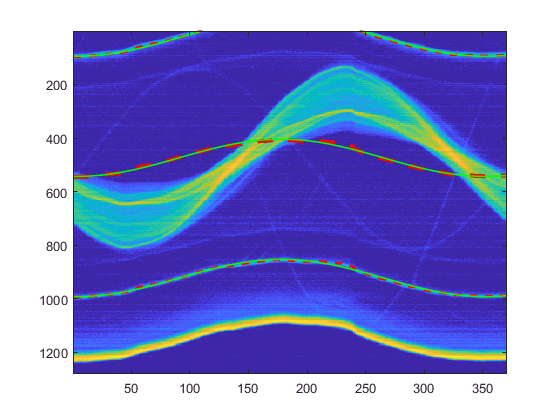

sino = double(squeeze(vid_data(1,:,:)) -0);
cap_peak_points = find_walls(sino, capillary_endpoints);
cap_mid = mean(cap_peak_points,2);
[fitted, offset] = fit_sine(cap_mid);
% vertical_adjustment = vertical_offset - image_width/2;
cap_width = nanmedian(diff(cap_peak_points,1,2));
cap_ideal_walls = [fitted - cap_width/2, fitted+cap_width/2];
% fprintf('Sinogram offset is %0.2f pixels\n',vertical_adjustment);

imagesc(sino);
hold on
plot(cap_peak_points,'--', 'LineWidth',2,'Color','red');

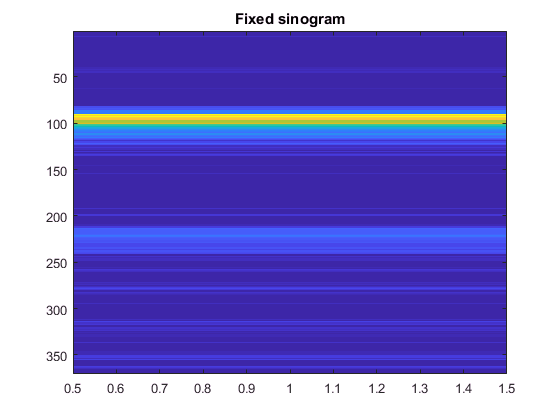

plot(cap_mid,'--', 'LineWidth',3,'Color','red');
% plot(y, '--', 'LineWidth',2,'Color','red')

plot(fitted, '-', 'LineWidth',1,'Color','green');
plot(cap_ideal_walls, '-','LineWidth',1,'Color','green');
hold off
imagesc(warp_sino(sino, offset));
title('Fixed sinogram');

original_y = cap_mid;
y = sgolayfilt(original_y, 3, 9);
x = [1:size(y)]';
yu = max(y);
yl = min(y);
yr = (yu-yl)/2;                               % Range of ‘y’
yz = y-yu+(yr);  % y centred around the origin
z = yz .* circshift(yz,[0 1]);
zx = x(z <= 10);     % Find zero-crossings
zdiff = diff(zx);
per = 360; %2*mean(zdiff(zdiff>1));                     % Estimate period
ym = nanmean(y);                               % Estimate offset
%estimate the phase - this helps a lot with the fitting function
[~, max_ix] = max(y);
if max_ix < 90
    pha = 90 - max_ix;
else
    pha = 450 - max_ix;
end
fit = @(b,x)  b(1).*(sin(deg2rad(360*x./b(2) + b(3)))) + b(4);    % Function to fit
fcn = @(b) nansum((fit(b,x) - y).^2);                              % Least-Squares cost function
[sinfit,fval,exitflag,output] = fminsearch(fcn, [yr;  per; pha;  ym]);                    % Minimise Least-Squares
 %fit to a sine curve, returns amplitude, period, phase, offset
% phase = sinfit(2)/(2*sinfit(3)); 
% phase=0;

Sine fitting complete after 127 iterations

if(exitflag==1)
    fprintf('Sine fitting complete after %d iterations',output.iterations);
else
    error('Sine fitting failed.');
end
phase=sinfit(3);
fitted = sin(deg2rad(phase + ([1:size(y,1)])*360/sinfit(2)))*sinfit(1);
original = sin(deg2rad(pha + ([1:size(y,1)])*360/360))*yr + ym;
vertical_offset = sinfit(4);

Sine fitted with max divergence 14.37 pixels and mean 0.0001


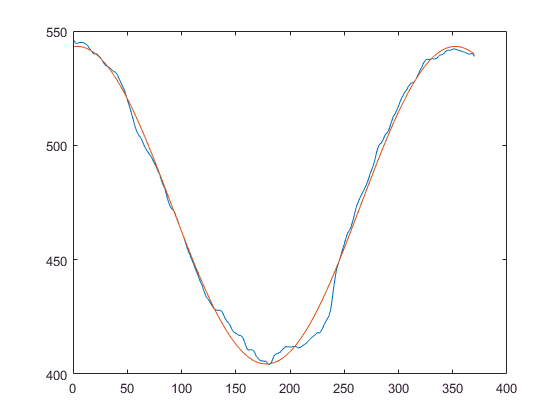

fitted = fitted + vertical_offset;
fitted = fitted';
offset = fitted-original_y; %how much do we need to warp the sinogram?
offset = fillmissing(offset, 'linear');
fprintf('Sine fitted with max divergence %0.2f pixels and mean %0.4f\n',max(abs(offset)),mean(offset));

plot(y);
hold on 
plot(fitted);
% plot(original);
hold off

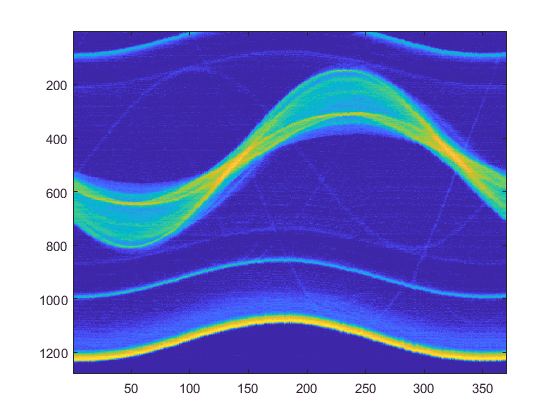

% dfield = ones(size(sino));
% dfield = dfield(:,1) .* -offset;


dfield = repmat(-offset,1,1280)';
dfield(:,:,2) = dfield(:,:,1);
dfield(:,:,1) = 0;
shifted_sino = imwarp(sino, dfield);
imagesc(shifted_sino);
% size(dfield)

## Get an example sinogram

% sino = (squeeze(vid_data(1,:,:)) -0);
% [offset, walls, midpoints, fitted] = get_sin_offset(sino);
% imagesc(sino);
% hold on;
% plot(walls);
% plot(midpoints);
% plot(fitted, '--');
% title("Uncorrected sinogram (slice 1280)");
% hold off;
% 
% s = warp_sino(sino, offset);
% 
% [offset, walls, midpoints, fitted] = get_sin_offset(s);
% imagesc(s);
% hold on;
% plot(walls);
% plot(midpoints);
% plot(fitted, '--');
% title("Corrected sinogram");
% hold off;

## Reconstruct sinogram of a single frame

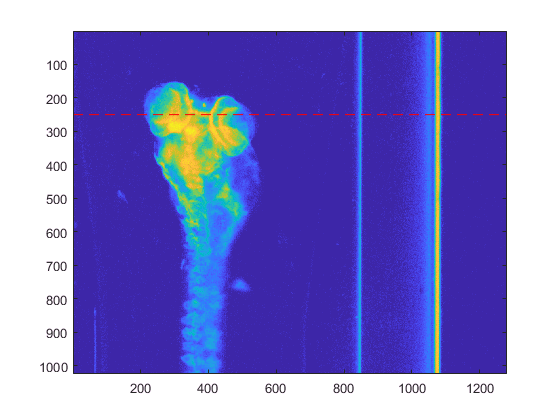

darklevel = 0;

slicenum = 250;
imagesc(vid_data(:,:,1)-darklevel);
% refline(0, slicenum, '--', 'LineWidth',2,'Color','red');
hline = refline(0,slicenum);

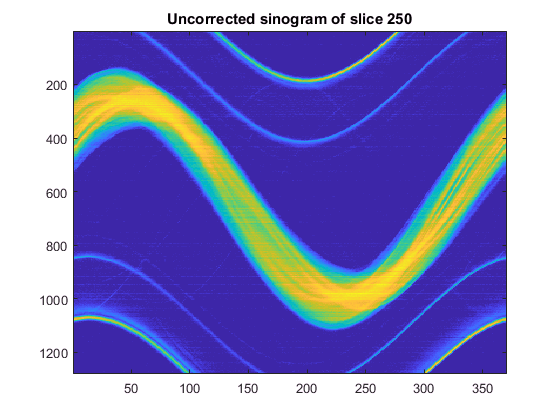

    set(hline,'color','r');
    set(hline,'LineStyle','--');
sino = (squeeze(vid_data(slicenum,:,:)) - darklevel); 

% for framenum = 1:numframes
%     sino(1:int16(cap_walls(slicenum,framenum,1))+25,framenum) = 0;
%     sino(int16(cap_walls(slicenum,framenum,2))-25:end,framenum) = 0;
% end

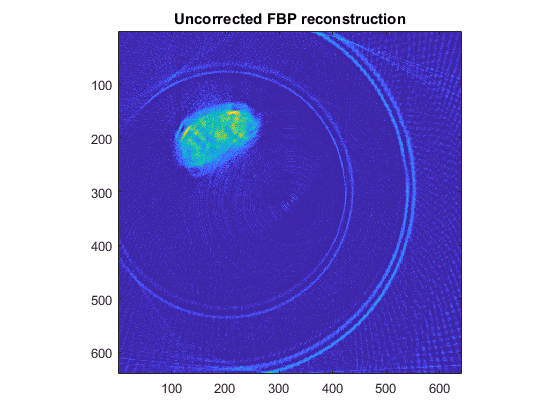

imagesc(sino);
title(sprintf('Uncorrected sinogram of slice %s', num2str(slicenum)));
small_sino = imresize(sino, 0.5);
small_angles = decimate(angles,2);
view = reconstruct_from_sino(small_sino', -small_angles, gpuAvailable);
view(view<0)=0;
imagesc(view)

title('Uncorrected FBP reconstruction');
daspect([1 1 1])

## Corrected reconstruction of that frame

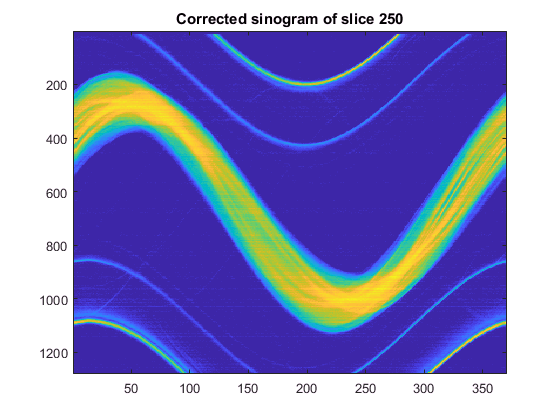


sino = double(squeeze(vid_data(slicenum,:,:)) - darklevel);
% mask out the walls
% extra_clip = 40; % number of pixels extra to mask out
% sino_mask = ones(size(sino));
% for framenum = 1:numframes
%     sino_mask(1:round(cap_ideal_walls(framenum,1))+extra_clip,framenum) = 0;
%     sino_mask(round(cap_ideal_walls(framenum,2))-extra_clip:end,framenum) = 0;
% end
small_sino_mask = imresize(sino_mask, 0.5);
s = imtranslate(sino, [0,-vertical_adjustment]);

imagesc(s)
title(sprintf('Corrected sinogram of slice %s', num2str(slicenum)))
small_sino = imresize(s, 0.5);
small_angles = decimate(angles,2);
tic;

Elapsed time is 1.246768 seconds.


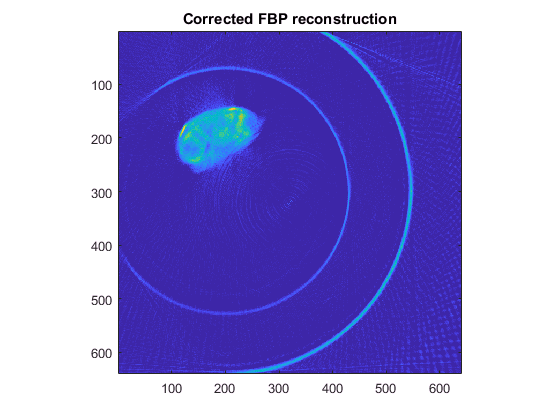

view = reconstruct_from_sino(small_sino', -small_angles,gpuAvailable);
toc
view(view<0)=0;
imagesc(view)

title('Corrected FBP reconstruction');
daspect([1 1 1])

## Optimise COR

subset = [1:4:numframes];
sino = (squeeze(vid_data(slicenum,:,:)) - darklevel);
fixed_sino = imtranslate(sino, [0,-vertical_adjustment-0], 'cubic');
%downsample for speed
downsamplefactor = 2;
small_sino = imresize(fixed_sino, 1/downsamplefactor);
small_angles = decimate(angles,downsamplefactor);
% subset for speed
tic;

Elapsed time is 13.198744 seconds.


view = reconstruct_from_sino(small_sino', -small_angles,gpuAvailable);

image_variance = 0.0137

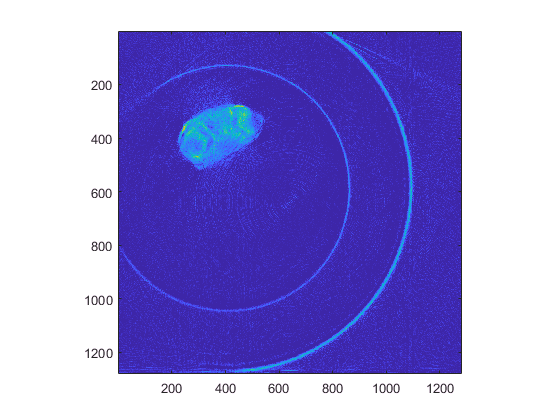

toc
image_variance = var(view(:))
view(view<0)=0;
imagesc(view);


daspect([1 1 1]);

## Reconstruct all sinograms



downsamplefactor = 4;
vol_width = image_width/downsamplefactor;
vol_height = numslices/downsamplefactor;
views = zeros(vol_width, vol_width, vol_height);
tic;
h = waitbar(0,'Processing...');
for slicenum = 1:downsamplefactor:numslices
    waitbar(slicenum/numslices, h, sprintf('Processing slice: %d',slicenum));
    sino = (squeeze(vid_data(slicenum,:,:)) );
    fixed_sino = imtranslate(sino, [0,-vertical_adjustment-0], 'cubic');
    small_sino = imresize(fixed_sino, 1/downsamplefactor);
    small_angles = decimate(angles,downsamplefactor);
    view = reconstruct_from_sino(small_sino', -small_angles,gpuAvailable);
    view(view<0)=0;
    views(:,:,uint16((slicenum-1)/downsamplefactor+1)) = view;
end

Elapsed time is 50.899715 seconds.


close(h);
toc

## Save the tiff stack

intview = uint8(round(views*64));
outputfilename = strcat(videoname,'-ch',int2str(colorchannel),'.tiff');
imwrite(intview(:,:,1),outputfilename);
for i = 2:size(intview,3)
    imwrite(intview(:,:,i),outputfilename,'WriteMode', 'append');
end

## Load another channel

videoname = 'OPT Lov-2017-09-12T18_23_33.compressed.avi';
video = read(VideoReader(videoname));
background = imread('background.bmp');
%video = (background - video);
video = imcomplement(video);
colorchannel = 3;
best_startframe = 10;
best_endframe = 382;
vid_data = squeeze(video(:,:,colorchannel,best_startframe:best_endframe));
angles = linspace(0,2*pi, best_endframe-best_startframe+1);
clear video